%PREPARATIONS
cd /media/anton/E6D8B24FD8B21E2D/Git/txcloud/Labs/CM/Larin_Anton_8383_CM_21_11/Solution
%cd D:\Git\TxCloud\Labs\CM\Larin_Anton_8383_CM_21_11\Solution

filename = "inp"

filename = "inp"

%MATRIX BY HANDS

%2
%0.5308 0.9304 0.5688
%0.7792 0.1299 0.4694

n=2;
M=[1 2 3;
4 5 6];

file = fopen(filename,'w');
fprintf(file,'%d\n',n);
for j = 1:size(M,1)  
    for i = 1:size(M,2)
        fprintf(file,"%d ",M(j,i));
    end
    fprintf(file,"\n");
end
fclose(file);
A = M(:,1:1:end-1)

A =      1     2
     4     5


b=M(:,end)

b =      3
     6


%RANDOM
n=randi([2,10],1,1)

n = 3

M=rand(n,n+1)

M =     0.6868    0.6256    0.9294    0.4359
    0.1835    0.7802    0.7757    0.4468
    0.3685    0.0811    0.4868    0.3063





file = fopen(filename,'w');
fprintf(file,'%d\n',n);
for j = 1:size(M,1)  
    for i = 1:size(M,2)
        fprintf(file,"%d ",M(j,i));
    end
    fprintf(file,"\n");
end
fclose(file);
A = M(:,1:1:end-1)

A =     0.6868    0.6256    0.9294
    0.1835    0.7802    0.7757
    0.3685    0.0811    0.4868


b=M(:,end)

b =     0.4359
    0.4468
    0.3063


%MATRIX FROM FILE
file = fopen(filename,'r');
raw=fscanf(file,"%f");
n=raw(1)

n = 4

raw=raw(2:end);
M=vec2mat(raw,n+1);
A = M(1:1:n,1:1:end-1)

A =     0.4039    0.9561    0.3532    0.1690
    0.0965    0.5752    0.8212    0.6491
    0.1320    0.0598    0.0154    0.7317
    0.9421    0.2348    0.0430    0.6477


b=M(1:1:n,end)

b =     0.4509
    0.5470
    0.2963
    0.7447



%PROCESS


ethalonRoots = A\b

ethalonRoots =     0.5589
    0.0639
    0.3248
    0.2921


%gauss
[~,out]=system("python3 main.py g 16 <"+filename)

out =     '0.5588918413482896
     0.06391340808328069
     0.3248066443802748
     0.2921027777212042
     '


%out="42"
pyRoots = str2num(out);
vpa(pyRoots,16)

$$ans = \left(\begin{array}{c} 0.5588918413482896\\ 0.06391340808328069\\ 0.3248066443802748\\ 0.2921027777212042 \end{array}\right)$$

%iter roots
[~,out]=system("python3 main.py i 16 10 <"+filename)

out =     '0.5588918413482896
     0.06391340808328069
     0.3248066443802748
     0.2921027777212042
     '


%out="42"
pyRoots = str2num(out)

pyRoots =     0.5589
    0.0639
    0.3248
    0.2921


%cond res

ethalonRoots = A\b

ethalonRoots =     0.5589
    0.0639
    0.3248
    0.2921



pr=8

pr = 8


res=[]


res =

     []



eps=[]


eps =

     []




while pr>0
    [~,out]=system("python3 main.py g "+pr+" <"+filename);
    pyRoots = str2num(out);
    res=[res,pyRoots];
    %v=zeros(1,n)'+pr;
    %mean(ethalonRoots-pyRoots);
    eps=[eps;pr,mean(ethalonRoots-pyRoots)];
    pr=pr-1;
end
eps

eps =     8.0000   -0.0000
    7.0000   -0.0000
    6.0000    0.0000
    5.0000    0.0000
    4.0000    0.0000
    3.0000   -0.0002
    2.0000    0.0008
    1.0000    0.0093


%for i=1:size(eps,2)
%    vpa(eps(:,i),10)
%end
x=eps(:,1)

x =      8
     7
     6
     5
     4
     3
     2
     1


y=real(log10(eps(:,2)))

y =   -16.3458
   -8.5625
   -7.0290
   -7.2250
   -5.1801
   -3.7052
   -3.0731
   -2.0300


vpa(eps,16)

$$ans = \left(\begin{array}{cc} 8.0 & -4.510281037539698e-17\\ 7.0 & -0.000000002738520823303281\\ 6.0 & 0.00000009354735744718234\\ 5.0 & 0.0000000595649677012644\\ 4.0 & 0.000006604723872167401\\ 3.0 & -0.0001971596882161218\\ 2.0 & 0.0008451011451691311\\ 1.0 & 0.009333429788024181 \end{array}\right)$$

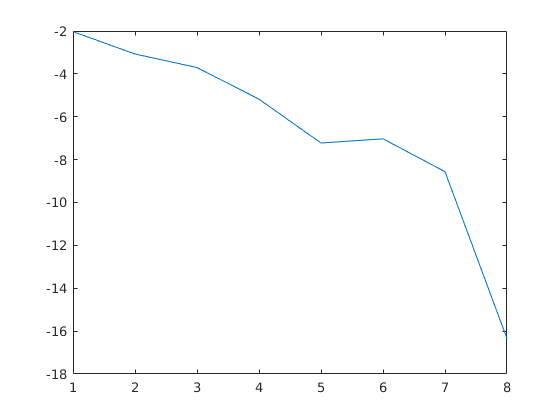

plot(x',y')


cond(A)

ans = 6.5014

eig(A)

ans =    1.7761 + 0.0000i
   0.0712 + 0.7954i
   0.0712 - 0.7954i
  -0.2762 + 0.0000i


ethalonRoots

ethalonRoots =     0.5589
    0.0639
    0.3248
    0.2921


pyRoots

pyRoots =     0.5238
    0.1429
    0.2024
    0.3333
